clear;clf;

% q1
G = tf([4 18],[1 4 18])

G =
 
     4 s + 18
  --------------
  s^2 + 4 s + 18
 
Continuous-time transfer function.



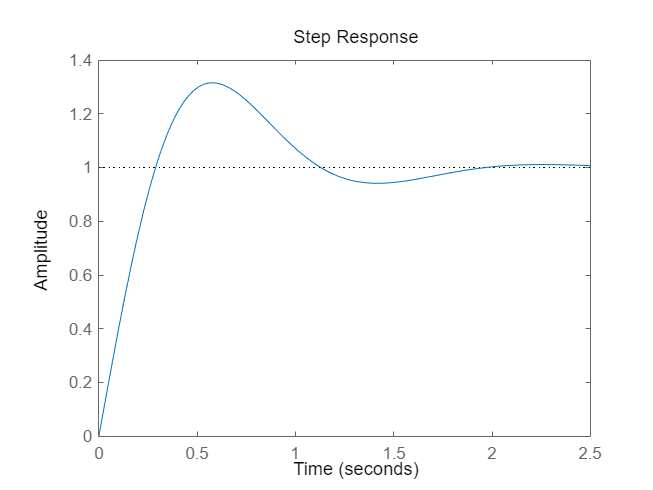

step(G)

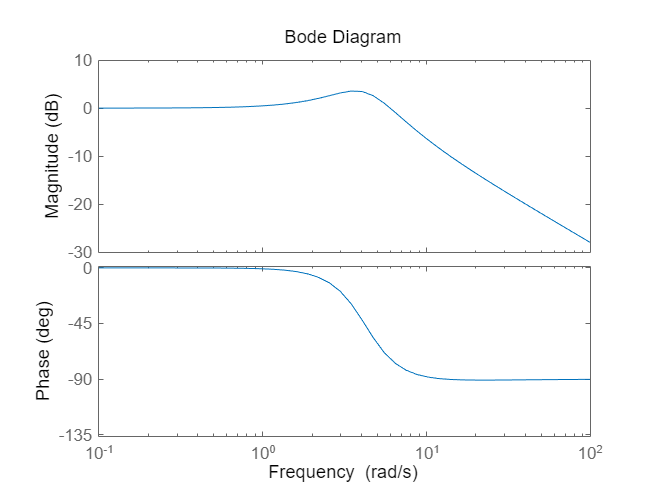

bode(G)

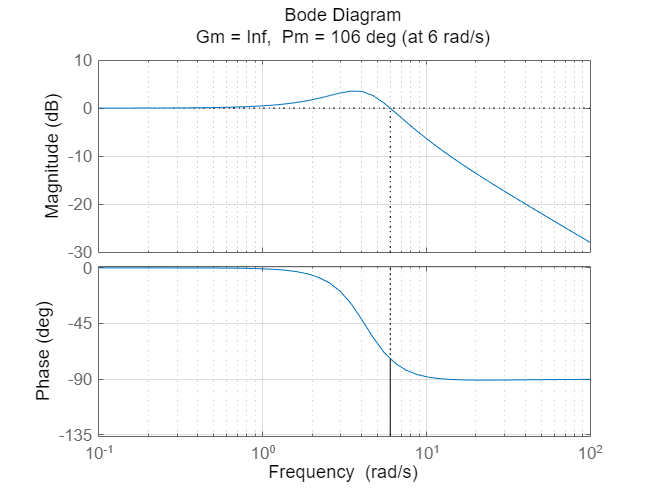

margin(G)
grid on

% q2
T = tf([3600],[1,84,3600])

T =
 
        3600
  -----------------
  s^2 + 84 s + 3600
 
Continuous-time transfer function.



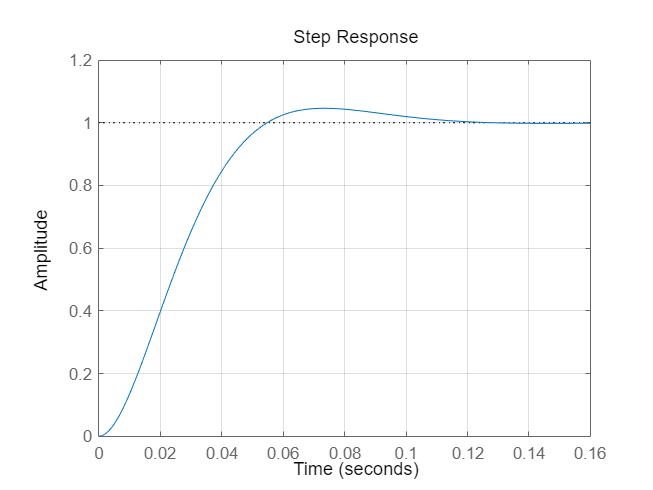

step(T)
grid on

G = tf([4 18],[2 4 18])

G =
 
      4 s + 18
  ----------------
  2 s^2 + 4 s + 18
 
Continuous-time transfer function.



[A,B,C,D] = tf2ss([4,18],[1,4,18])

A =     -4   -18
     1     0


B =      1
     0


C =      4    18


D = 0

tf(ss([0,1;-9,-2],[0;1],[9,2],0))

ans =
 
     2 s + 9
  -------------
  s^2 + 2 s + 9
 
Continuous-time transfer function.



% q3
G = tf([1,0],[1,0,18])

G =
 
     s
  --------
  s^2 + 18
 
Continuous-time transfer function.



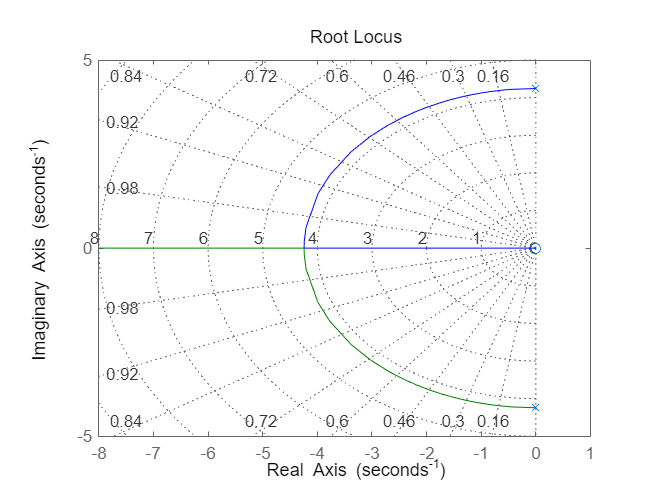

rlocus(G)
grid on

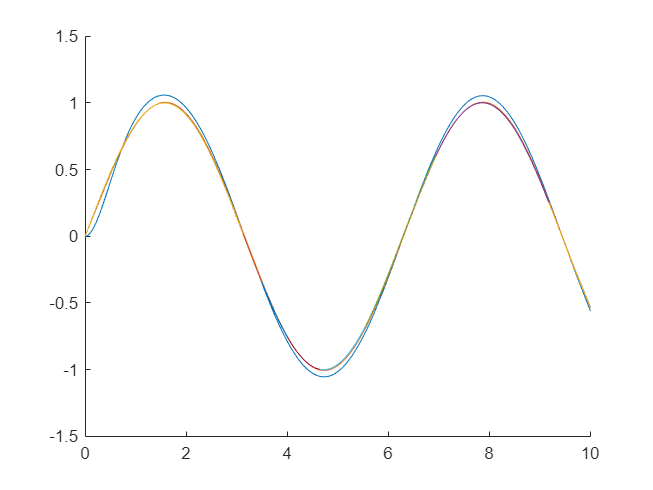

syms s t
clf;
hold on
v1 = [1:15:31];
b1 = [5:50:500];
for i = 1:1
    for j=1:10
        v = v1(i);
        b = b1(j);
        x = v*(b*s+18)/(s^2+v^2)/(s^2+b*s+18);
        f = ilaplace(x,s,t);
        fplot(t,f,[0 10])
    end
end

syms v
clf;
hold off
r = 55-5*v*heaviside(v)+5*v*heaviside(v-10)-50*heaviside(v-10)

$$r = 5\,v\,\mathrm{heaviside}\left(v-10\right)-50\,\mathrm{heaviside}\left(v-10\right)-5\,v\,\mathrm{heaviside}\left(v\right)+55$$

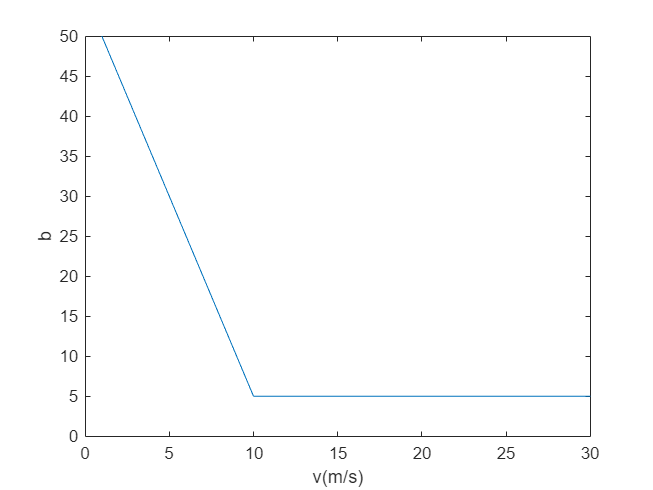

fplot(v,r,[0,30])
ylim([0 50])
xlabel('v(m/s)')
ylabel('b')

syms s
v = 1

v = 1

sys = v*3600/(s^2+v^2)/(s^2+84*s+3600)*(s^2+0.01)

$$sys = \frac{3600\,\left(s^{2}+\frac{1}{100}\right)}{\left(s^{2}+1\right)\,\left(s^{2}+84\,s+3600\right)}$$

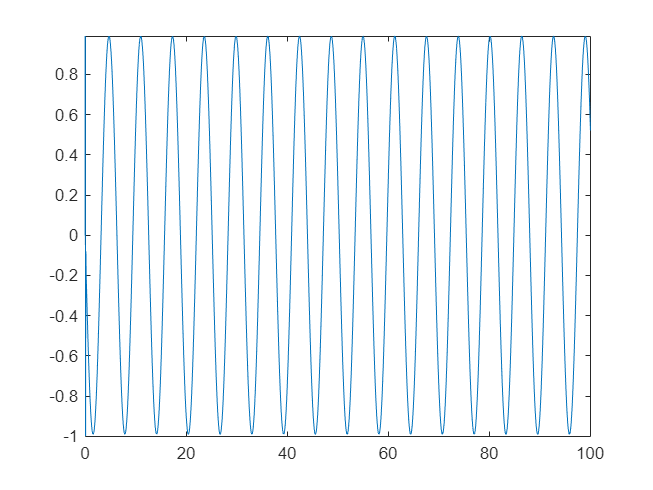

fplot(ilaplace(sys),[0,100])

syms v
clf;
hold on
r = 5495/99-50/99*v*v

$$r = \frac{5495}{99}-\frac{50\,v^{2}}{99}$$

fplot(v,r,[0,10],'Color','b')
u = 5

u = 5

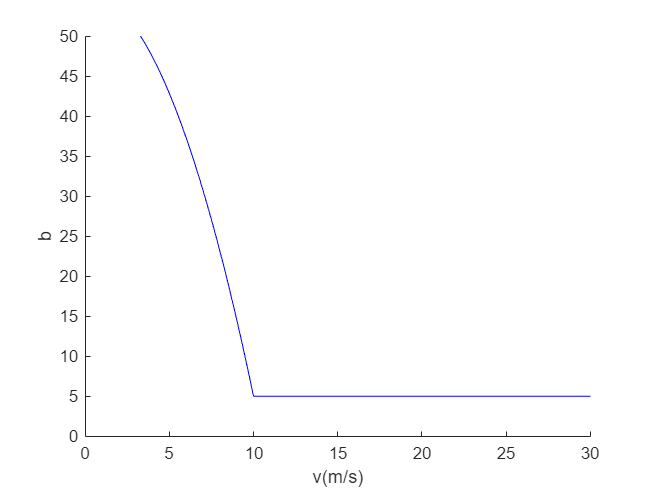

fplot(u,[10 30],'Color','b')
ylim([0 50])
xlabel('v(m/s)')
ylabel('b')